% Generate p1
p1 =[0 0 0 0; 0 -1 -2 -3]'

p1 =      0     0
     0    -1
     0    -2
     0    -3


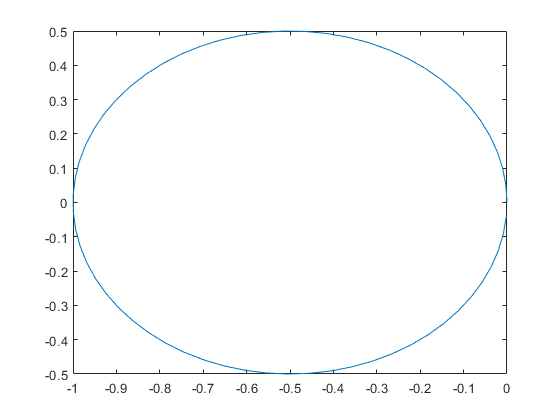

p2 =          0         0
   -0.0025    0.0499
   -0.0100    0.0993
   -0.0223    0.1478
   -0.0395    0.1947
   -0.0612    0.2397
   -0.0873    0.2823
   -0.1176    0.3221
   -0.1516    0.3587
   -0.1892    0.3917


%Generate p2 using circle function at the bottom of the file
p2=circle(0,0,0.5)

plot(p2(:,1),p2(:,2))

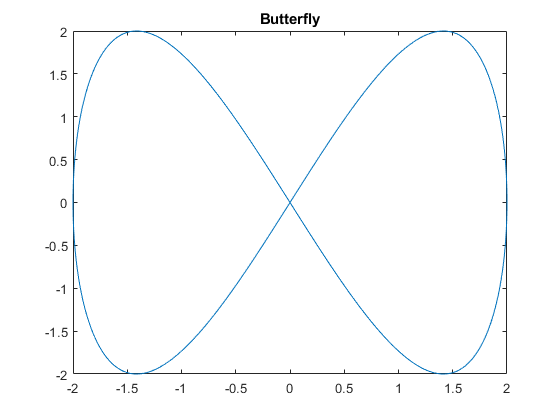

%Generate p3 and p4. 
wingWidth = 2;
wingHeight = 2;

freq = 2* pi / 30 ;
Ts = 0.033 ; % Sampling time
t = 0 :Ts:30 ; % S i m u l a t i o n time
xRef = 0 +wingWidth *sin(freq*t) ;
yRef = 0 - wingHeight * sin( 2*freq*t) ;
plot( xRef, yRef) ;
title('Butterfly') ;

p3 =[0 xRef ; 0 yRef ]'

p3 =          0         0
         0         0
    0.0138   -0.0276
    0.0276   -0.0553
    0.0415   -0.0829
    0.0553   -0.1105
    0.0691   -0.1381
    0.0829   -0.1657
    0.0967   -0.1932
    0.1105   -0.2207


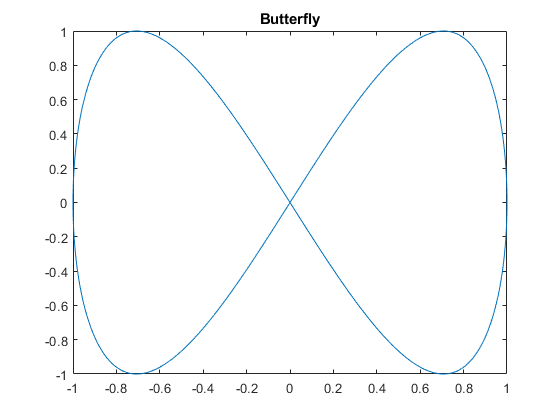


wingWidth2 = 1;
wingHeight2 = 1;

freq = 2* pi / 30 ;
Ts = 0.033 ; % Sampling time
t = 0 :Ts:30 ; % S i m u l a t i o n time
xRef = 0 +wingWidth2 *sin(freq*t) ;
yRef = 0 - wingHeight2 * sin( 2*freq*t) ;
plot( xRef, yRef) ;
title('Butterfly') ;

p4 =[0 xRef ; 0 yRef ]'

p4 =          0         0
         0         0
    0.0069   -0.0138
    0.0138   -0.0276
    0.0207   -0.0415
    0.0276   -0.0553
    0.0346   -0.0691
    0.0415   -0.0828
    0.0484   -0.0966
    0.0553   -0.1104


%Equation Piste : p5

ligneDroite1=[0 0 0 0; 0 -0.3 -0.6 -1]'

ligneDroite1 =          0         0
         0   -0.3000
         0   -0.6000
         0   -1.0000


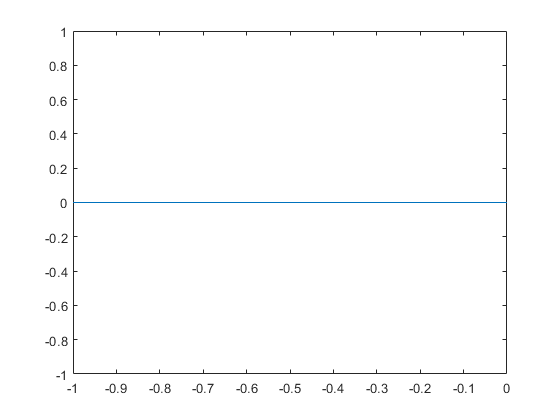

plot(ligneDroite1(:,2),ligneDroite1(:,1))

ligneDroite2=[1 1 1 1;-1 -0.6 -0.3 0]'

ligneDroite2 =     1.0000   -1.0000
    1.0000   -0.6000
    1.0000   -0.3000
    1.0000         0


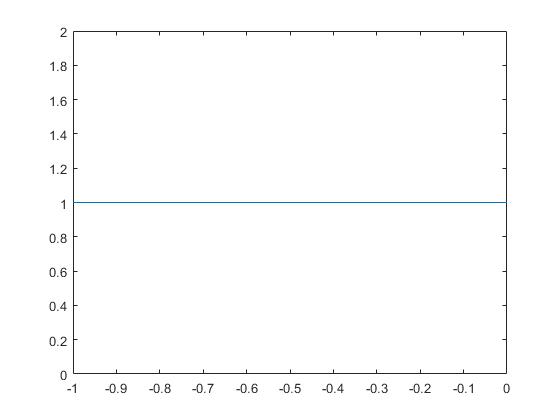

plot(ligneDroite2(:,2),ligneDroite2(:,1))

demicercle1=flip(halfcircle1(0.5,-1,0.5))

demicercle1 =     0.0004   -1.0208
    0.0050   -1.0706
    0.0145   -1.1196
    0.0289   -1.1675
    0.0480   -1.2137
    0.0716   -1.2578
    0.0994   -1.2992
    0.1313   -1.3377
    0.1669   -1.3729
    0.2057   -1.4042


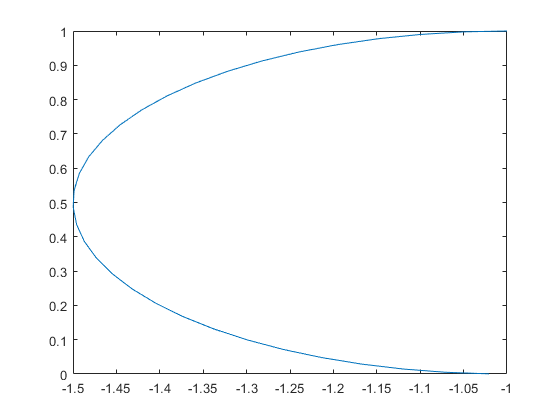

plot(demicercle1(:,2),demicercle1(:,1))

demicercle2=halfcircle2(0.5,0,0.5)

demicercle2 =     1.0000         0
    0.9975    0.0499
    0.9900    0.0993
    0.9777    0.1478
    0.9605    0.1947
    0.9388    0.2397
    0.9127    0.2823
    0.8824    0.3221
    0.8484    0.3587
    0.8108    0.3917


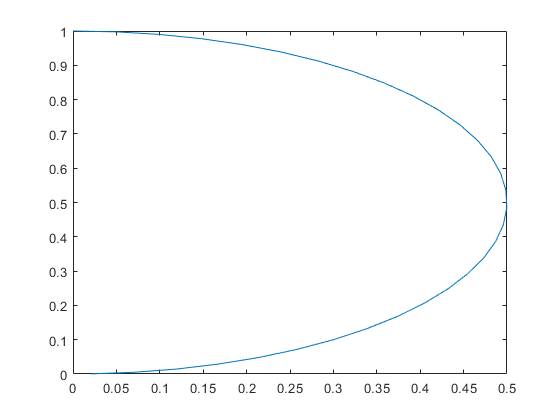

plot(demicercle2(:,2),demicercle2(:,1))


circuit=[ligneDroite1;ligneDroite2;demicercle1;demicercle2]

circuit =          0         0
         0   -0.3000
         0   -0.6000
         0   -1.0000
    1.0000   -1.0000
    1.0000   -0.6000
    1.0000   -0.3000
    1.0000         0
    0.0004   -1.0208
    0.0050   -1.0706




circuit=[circuit;circuit;circuit;circuit]

circuit =          0         0
         0   -0.3000
         0   -0.6000
         0   -1.0000
    1.0000   -1.0000
    1.0000   -0.6000
    1.0000   -0.3000
    1.0000         0
    0.0004   -1.0208
    0.0050   -1.0706


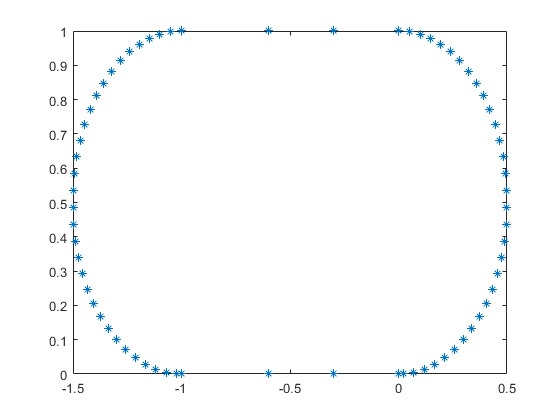

plot(circuit(:,2),circuit(:,1),"*")

function p=circle(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    ang=0:0.1:2*pi; 
    xp=r*cos(ang)-0.5;
    yp=r*sin(ang);
    plot(x+xp,y+yp);
    p=[x+xp;y+yp]';
end

function p=halfcircle1(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    ang=0:0.1:pi; 
    xp=r*cos(ang);
    yp=-r*sin(ang);
    p=[x+xp;y+yp]';
end

function p=halfcircle2(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    ang=0:0.1:pi; 
    xp=r*cos(ang);
    yp=r*sin(ang);
    p=[x+xp;y+yp]';
end